# Interactive MATLAB Lab 1.2: Ordinary or Partial?

In a Live Script, turn "example" into a drop-down control.

Partial Differential Equation


Equation: u_t = u_xx


Candidate solution:


$${\mathrm{e}}^{-t}\,\sin\left(x\right)$$

Independent variables: 2 (x and t)


Derivative type: partial derivatives


Time derivative:


$$-{\mathrm{e}}^{-t}\,\sin\left(x\right)$$

Second space derivative:


$$-{\mathrm{e}}^{-t}\,\sin\left(x\right)$$

Verification:


   1



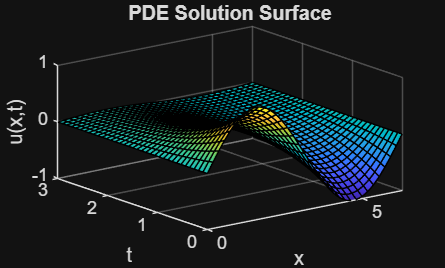

example = "PDE";   % Options: "ODE", "PDE"

syms x t

switch example
    case "ODE"
        candidate = exp(2*x);
        lhs = diff(candidate,x);
        rhs = 2*candidate;
        residual = simplify(lhs-rhs);
        check = isequal(residual,sym(0));

        disp("Ordinary Differential Equation")
        disp("Equation: v' = 2v")
        disp("Candidate solution:")
        disp(candidate)
        disp("Independent variables: 1")
        disp("Derivative type: ordinary derivative")
        disp("Verification:")
        disp(check)

        figure
        fplot(candidate,[-2 2],'LineWidth',1.5)
        grid on
        xlabel('x')
        ylabel('v(x)')
        title('ODE Solution')

    case "PDE"
        candidate = exp(-t)*sin(x);
        dt = diff(candidate,t);
        dxx = diff(candidate,x,2);
        residual = simplify(dt-dxx);
        check = isequal(residual,sym(0));

        disp("Partial Differential Equation")
        disp("Equation: u_t = u_xx")
        disp("Candidate solution:")
        disp(candidate)
        disp("Independent variables: 2 (x and t)")
        disp("Derivative type: partial derivatives")
        disp("Time derivative:")
        disp(dt)
        disp("Second space derivative:")
        disp(dxx)
        disp("Verification:")
        disp(check)

        figure
        fsurf(@(x,t) exp(-t).*sin(x),[0 2*pi 0 3])
        xlabel('x')
        ylabel('t')
        zlabel('u(x,t)')
        title('PDE Solution Surface')
end